# SIM optimization (2D-DFT)

Description: The code follows the algorithm introduced in reference [1, Section II] and [2, Section III], to find the SIM elements that approximates the 2D-DFT. This code evaluates the phase shift $\xi_{l,m} \in[0,2 \pi)$ of each meta-atom in the SIM (only for the intermediate layers). Intermediate layers correspond to all the layers beneath the input layer, see Fig. 1. 

The propagation of the waveform through the SIM is modeled with the attenuation coefficients between SIM layers, and the transmission coefficient for each meta-atom, given by $\Gamma_{l,m}=e^{j\xi_{l,m}}$. In practice, the transmission coefficients are adjusted by controlling the bias voltage on each meta-atom. The attenuation coefficients are modeled with the Rayleigh-Sommerfeld difraction equation [2, Eq. (7)], and in practice they are fixed, as they depend on the geometry of the SIM and the frequency of the waveform.

The coefficient which defines the transmission parameter of each single SIM element.

The optimization problem to solve is the following

$\min_{\xi_{l,m}} \;\; \mathcal L=\|\beta G - F\|_F^2$ (1)


$$\text{s.t. }$$


$G = W_L \Upsilon_L \cdots W_1\Upsilon_1 W_0,$ $\mathbf{G}\,\in\,\mathbb{C}^{N_x\times N_y}$             (2)

$\Upsilon_l=\mathrm{diag}(e^{j\xi_{l,1}},\dots,e^{j\xi_{l,M}}) \]$                              (3)

$\xi_{l, m} \in[0,2 \pi), \quad m=1, \cdots, M,\quad l=1, \cdots, L$ (4)

where 

- $l$ is the intermediate index layer

- $L$ is the number of intermediate layers

- $\beta \in \mathbb{C}$ is a scaling factor and evaluated as [Eq. (21), 1]

             $\beta=(g^{H}g)^{-1}g^{H}f$                           (5)

             where $g=\text{vec}{(G)}$ and $f=\text{vec}{(F)}$. The $\text{vec}(\cdot)$ operation refers to concatenating each column of the matrix to construct a vector.

Besides

- $m$ is the meta-atom index in the layer $l$. This index encodes linearly the 2D position of the meta-atom as follows:

- $m_{y}= \left \lceil {{ m/M_{{x}} }}\right \rceil$               (6)

- $m_{x}= m-\left( m_{y}-1\right) M_{x}$  (7)

- $M$ is the number of meta-atoms on each intermediate layer

$F$ is the matrix that represents the 2D-DFT as

$\left [{{ \textbf{F} }}\right ]_{n,{n_\psi}}\triangleq e^{-j2\pi \frac {\left ({{ n_{\psi_{\textrm {x}}}-1 }}\right) \left ({{ n_{\textrm {x}}-1 }}\right)}{N_{\textrm {x}}}}e^{-j2\pi \frac {\left ({{ n_{\psi_{\textrm {y}}}-1 }}\right)\left ({{ n_{\textrm {y}}-1 }}\right)}{N_{\textrm {y}}}}, \mathbf{F}\,\in\,\mathbb{C}^{N_x\times N_y}$ (8)

where $n_x$ and $n_y$ refers to the coordinates of each patch element in the input layer of the SIM, and $n_{\psi_x}$ and $n_{\psi_y}$ refer to the coordinates on the transform domain (angular), where the electric angles are estimated.

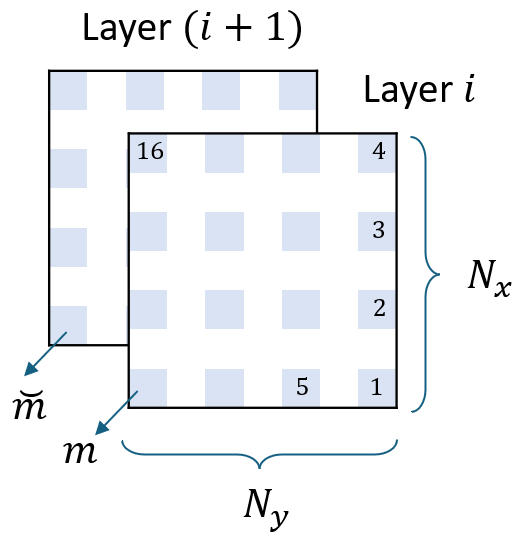

Fig. 1: Coordinates of each meta-atom in the input layer of the SIM

$W_l\in\mathbb{C}^{M\times M}$ is the matrix that evaluates the EM propation between atoms from adjacent layers, where $W_L, W_0 \, \in\mathbb{C}^{N\times N}$. These matrices are evaluated based on the Rayleigh-Sommerfeld diffraction equation as follows [Eq. (7), 1]:

$[\mathbf{W}_{l}]_{n, \breve{n}}=\frac{A_{\text {meta-atom }} s_{\text {layer }}}{2 \pi d_{n, \breve{n}}^{3}}(1-j \kappa d_{n, \breve{n}}) e^{j \kappa d_{n, \breve{n}}}$ (9)

where $A_{\text {meta-atom }$ is the area of each meta-atom, $k=\frac{2\pi}{\lambda}$ is the waveform number. The variable $d$ refers to the propagation distance between the atoms coordinates $n$ and $\breve n$

$d_{n, \breve{n}}=\sqrt{(n_{\mathrm{x}}-\breve{n}_{\mathrm{x}})^{2} s_{\mathrm{x}}^{2}+(n_{\mathrm{y}}-\breve{n}_{\mathrm{y}})^{2} s_{\mathrm{y}}^{2}+s_{\text {layer }}^{2}}$ (10)

where $n$ is the coordinates of the atom in the $l$ layer and $\breve{n}$ is the coordinate of the atom in the $(l+1)$ layer. Their $(x,y)$ coordinates are evaluated as indicated in Eqs. (5)-(6).

where $s_x$, $s_y$, and $s_\text{layer}$ are the distances between elements in $x$-direction, $y$-direction, and between consecutive layers, see Fig. 2

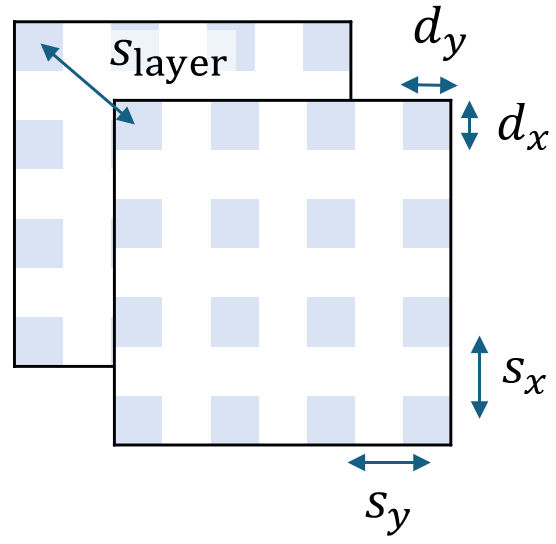

Fig. 2: Dimensions and distances parameters between meta-atoms.

The $W_L\in\mathbb{C}^{M\times N}$matrix, where $N$are the number of atoms in the input layer is also calculated with the Rayleight-Sommerfeld equation in Eq. (9).

The purpose of this code is to find the variables ${\xi_{l,m}$ for each patch element $m$ on each intermediate layer $m$. This code follows the Gradient Descent algorithm as described in [Eq. (19), 1] as follows

$\xi_{l,m}^{(k)}\leftarrow\xi_{l,m}^{(k-1)}-\eta\nabla_{\xi_{l,m}^{(k-1)}}\mathcal{L}$ (10)

where $\eta$ is a dynamic learning rate that is updated on each $k$-th iteration according to 

$\eta^{(k)} \leftarrow \eta^{(k-1)} \frac{\zeta \pi}{ \max _{l=1,2, \cdots, L}\{\max \nabla_{{\xi}_{l}} \mathcal{L}\}}$ (11)

The parameter $\zeta$ controls the maximum phase rotation per iteration as 

$\max_{l,m}|\Delta \epsilon_{l,m}|\leq\zeta \pi$ (12)

Smaller values of $\zeta$ means faster convergence.

The iterative process in $k$ runs till the following condition is met

$\frac{|\mathcal{L}^{(k)}-\mathcal{L}^{(k-1)}|}{ \max \{\mathcal{L}^{(k-1)}\}}< \text{tol}$ (13)

which tells about the control on the variability of $\mathcal{L}$ in Eq. (1) above.

The $m$-th entry of gradient of $\mathcal{L}$ is calculated as follows [Eq. (15), 1]:

$\nabla_{{\xi}_{l}} \mathcal{L}=2 \sum_{n=1}^{N} \Im\left\{\beta^{*} {\Upsilon}_{l}^{H} {P}_{l, n}^{H}(\beta {g}_{n}-{f}_{n})\right\}$ (13)

where $g=\text{vec}{(G)}$ and $f=\text{vec}{(F)}$, $e^H_m$ is the $m$-th row of the identity matrix $I_M$, and ${P}_{l, n}$ is given by [Eq. (16), 1]

${P}_{l, n}={W}_{L} {\Upsilon}_{L} {W}_{L-1} \cdots {W}_{l+1} {\Upsilon}_{l+1} {W}_{l} \text{diag}({q}_{l, n})$ (14)

and ${q}_{l, n}$ is given by [Eq. (17), 1]

${q}_{l, n}={W}_{l-1} {\Upsilon}_{l-1} {W}_{l-2} \cdots {W}_{2} {\Upsilon}_{2} {W}_{1} {\Upsilon}_{1} {w}_{0, n}$ (15)

and $w_{0,n}$ is the $n$-th column of $W_0$.

clc;
clear all;
close all;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\SIM\code



Parameters

total_iteration = 1

Wireless packet type: SC


T_coh = 0.0142

T =      1     4     9    16    25    36    49    64    81   100   121   144   169   196   225   256   289   324   361   400   441   484   529   576   625


T = 144

SNR_dB = 18.2642

% TRAIN_SIM_TO_DFT  Gradient descent training of SIM so G ~ beta^{-1} F
% Follows [Sec. III-B, Eqs. (18)-(21), (19)-(20), 1]
%
% Key dimensions:
%   N = N_x*N_y    (input/output layer meta-atoms & receiver probes)
%   M = M_x*M_y    (meta-atoms per intermediate layer)
%   L            (number of intermediate layers, layers 1..L)
%
% NOTE: Input layer phases (layer 0) are NOT trained here (paper keeps them for protocol later).
%
% Returns trained xi{l} vectors, and beta history.

rng(seed);

% Evaluating target 2D-DFT matrix F (Eq. 5) as
F = dft2_matrix(N_x, N_y);   % N_xN_y x N_xN_y, matches paper definition. [Eq. (11), 1]

% -------------------- Build propagation matrices W0, Wl, WL --------------------
%Input layer
% W0: M x N (input layer -> layer 1), Eq. (6)
W0 = build_W0(M_x, M_y, N_x, N_y, s_x, s_y, d_x, d_y, s_layer, waveform_k, A_atom);

%Intermediate layer
% Wl: M x M for l=1..L-1 (between intermediate layers)
W = cell(L-1,1);
for l = 1:(L-1)
    W{l} = build_W_MM(M_x, M_y, s_x, s_y, s_layer, waveform_k, A_atom); % same each hop if geometry constant
end

%Output layer
% WL: N x M (layer L -> output layer)
WL = W0.';   % paper in [1] notes WL = W0^T under isomorphic arrangement. :contentReference[oaicite:5]{index=5}

% -------------------- Initialize phases xi_l,m --------------------
%Phases are randomly initialized on each layer l of a total of L layers
xi = cell(L,1);
for l = 1:L
    xi{l} = 2*pi*rand(M,1);  % in [0,2pi)
end

eta = eta0;
beta = 1+0j;

loss_hist = zeros(maxIter,1);
beta_hist = zeros(maxIter,1);

% -------------------- Main Gradient Descent loop --------------------
for it = 1:maxIter

    it/maxIter*100
    % ----- Forward compute G = WL*Gamma_L*W_{L-1}*...*Gamma_1*W0  [Eq. (2)] -----
    [G, Gamma] = forward_G(WL, W, W0, xi); 

    % ----- Update beta by LS: beta = (g^H g)^(-1) g^H f  (eq. 21) -----
    g = G(:);% place the matrix into a vector concatenating the columns of G
    f = F(:);% place the matrix into a vector concatenating the columns of F
    beta = (g' * g) \ (g' * f);  % complex scalar

    % ----- Loss L = ||beta G - F||_F^2 (eq. 12) -----
    E = beta*G - F;
    Lval = norm(E,'fro')^2;% evaluates the Frobenius norm of the matrix E, which is sum(E^2_ij)
    loss_hist(it) = Lval;
    beta_hist(it) = beta;

    % % stopping
    % if it > 1 && abs(loss_hist(it)-loss_hist(it-1))/max(1,loss_hist(it-1)) < tol
    %     loss_hist = loss_hist(1:it);
    %     beta_hist = beta_hist(1:it);
    %     break;
    % end

    % ----- Compute gradients per layer using eq. (18) -----
    % ∇_{xi_l} L = 2 * sum_{n=1}^N Im{ beta^* * Gamma_l^H * P_{l,n}^H * (beta g_n - f_n) }
    % where g_n and f_n are n-th columns of G and F, and P_{l,n} defined in eq. (16).
    grads = cell(L,1);

    % Precompute columns of error:
    % e_n = (beta g_n - f_n)
    % We'll need P_{l,n}^H * e_n for each n.
    % For small N, loop n is fine.
    % for l = 1:L
    %     grads{l} = zeros(M,1);
    % end

    %Evaluates the Eq. (14) except for the vector q. This is computed for all the layers l of a total of L .
    % post = (WL*Gamma_L*W_{L-1}*...*W_{l})
    post = backward_post_products(WL, W, Gamma); % post{l}: N x M corresponds to WL*Gamma_L*W_{L-1}*Gamma_{L-1}*...*W_l

    for l = 1:L %looping in the number of layers
        grads{l} = zeros(M,1);

        for n = 1:N %looping over the gradient total of elements
            e_n = E(:,n); % (beta g_n - f_n)
    
            % Compute q_{l,n} for each layer l via forward propagation from input to layer l, as follows from Eq. (14)
            % q_{l,n} = W_{l-1}*Gamma_{l-1}*...*W1*Gamma1*w0_n.
            w0_n = W0(:,n);
            q = forward_q_all_layers(W, Gamma, w0_n); % q{l}: M_x1 illumination at layer l
                
            % P_{l,n} = post{l} * diag(q_{l,n})
            % So P_{l,n}^H * e_n = diag(conj(q)) * post{l}^H * e_n
            tmp = post{l}' * e_n;              % M_x1
            PlH_en = conj(q{l}) .* tmp;        % M_x1  (diag(conj(q))*tmp)

            % Solving for the gradient in Eq. (13): 2*Im{ beta^* * Gamma_l^H * PlH_en }
            % Gamma_l^H is diag(conj(u_l)) i.e., elementwise multiply by conj(u_l).
            %u_l = diag(Gamma{l});                  % M_x1 = exp(j*xi_l)
            grads{l} = grads{l} + 2*imag(conj(beta) * (conj(diag(Gamma{l})) .* PlH_en));
         end
    end

    % ----- Update phases xi_l <- xi_l - eta * grad  in Eq. (11) -----
    % then wrap to [0, 2pi)
    maxGrad = 0;
    for l = 1:L
        maxGrad = max(maxGrad, max(abs(grads{l})));
    end

    % learning-rate schedule (eq. 20): eta <- eta * zeta * pi / max_l max grad
    eta = eta * zeta * pi / max(1e-12, maxGrad);  % avoid divide-by-zero :contentReference[oaicite:9]{index=9}

    for l = 1:L
        xi{l} = xi{l} - eta * grads{l};
        xi{l} = mod(xi{l}, 2*pi);
    end

    % fprintf('it=%d, loss=%.3e, |beta|=%.3f, eta=%.3e\n', it, Lval, abs(beta), eta);
end

ans = 0.5000

ans = 1

ans = 1.5000

ans = 2

ans = 2.5000

ans = 3

ans = 3.5000

ans = 4

ans = 4.5000

ans = 5

ans = 5.5000

ans = 6

ans = 6.5000

ans = 7.0000

ans = 7.5000

ans = 8

ans = 8.5000

ans = 9

ans = 9.5000

ans = 10

ans = 10.5000

ans = 11

ans = 11.5000

ans = 12

ans = 12.5000

ans = 13

ans = 13.5000

ans = 14.0000

ans = 14.5000

ans = 15

ans = 15.5000

ans = 16

ans = 16.5000

ans = 17

ans = 17.5000

ans = 18

ans = 18.5000

ans = 19

ans = 19.5000

ans = 20

ans = 20.5000

ans = 21

ans = 21.5000

ans = 22

ans = 22.5000

ans = 23

ans = 23.5000

ans = 24

ans = 24.5000

ans = 25

ans = 25.5000

ans = 26

ans = 26.5000

ans = 27

ans = 27.5000

ans = 28.0000

ans = 28.5000

ans = 29.0000

ans = 29.5000

ans = 30

ans = 30.5000

ans = 31

ans = 31.5000

ans = 32

ans = 32.5000

ans = 33

ans = 33.5000

ans = 34

ans = 34.5000

ans = 35

ans = 35.5000

ans = 36

ans = 36.5000

ans = 37

ans = 37.5000

ans = 38

ans = 38.5000

ans = 39

ans = 39.5000

ans = 40

ans = 40.5000

ans = 41

ans = 41.5000

ans = 42

ans = 42.5000

ans = 43

ans = 43.5000

ans = 44

ans = 44.5000

ans = 45

ans = 45.5000

ans = 46

ans = 46.5000

ans = 47

ans = 47.5000

ans = 48

ans = 48.5000

ans = 49

ans = 49.5000

ans = 50

ans = 50.5000

ans = 51

ans = 51.5000

ans = 52

ans = 52.5000

ans = 53

ans = 53.5000

ans = 54

ans = 54.5000

ans = 55.0000

ans = 55.5000

ans = 56.0000

ans = 56.5000

ans = 57.0000

ans = 57.5000

ans = 58.0000

ans = 58.5000

ans = 59

ans = 59.5000

ans = 60

ans = 60.5000

ans = 61

ans = 61.5000

ans = 62

ans = 62.5000

ans = 63

ans = 63.5000

ans = 64

ans = 64.5000

ans = 65

ans = 65.5000

ans = 66

ans = 66.5000

ans = 67

ans = 67.5000

ans = 68

ans = 68.5000

ans = 69

ans = 69.5000

ans = 70

ans = 70.5000

ans = 71

ans = 71.5000

ans = 72

ans = 72.5000

ans = 73

ans = 73.5000

ans = 74

ans = 74.5000

ans = 75

ans = 75.5000

ans = 76

ans = 76.5000

ans = 77

ans = 77.5000

ans = 78

ans = 78.5000

ans = 79

ans = 79.5000

ans = 80

ans = 80.5000

ans = 81

ans = 81.5000

ans = 82

ans = 82.5000

ans = 83

ans = 83.5000

ans = 84

ans = 84.5000

ans = 85

ans = 85.5000

ans = 86

ans = 86.5000

ans = 87

ans = 87.5000

ans = 88

ans = 88.5000

ans = 89

ans = 89.5000

ans = 90

ans = 90.5000

ans = 91

ans = 91.5000

ans = 92

ans = 92.5000

ans = 93

ans = 93.5000

ans = 94

ans = 94.5000

ans = 95

ans = 95.5000

ans = 96

ans = 96.5000

ans = 97

ans = 97.5000

ans = 98

ans = 98.5000

ans = 99

ans = 99.5000

ans = 100


% out.xi = xi;
% out.beta = beta;
% out.loss_hist = loss_hist;
% out.beta_hist = beta_hist;
% out.params = params;


% ======================= Helpers =======================

function F = dft2_matrix(Nx, Ny)
% Matches eq. (11): F(n,nhat) = exp(-j2pi (nx-1)(nhx-1)/Nx) * exp(-j2pi (ny-1)(nhy-1)/Ny)
N = Nx*Ny;
F = zeros(N,N);
for n = 1:N
    [nx, ny] = ind2sub([Nx, Ny], n); % careful: Matlab ind2sub uses column-major; we want nx fastest
    % We'll define our own mapping: nx = mod(n-1,Nx)+1, ny = floor((n-1)/Nx)+1
    nx = mod(n-1, Nx) + 1;
    ny = floor((n-1)/Nx) + 1;
    for nh = 1:N
        nhx = mod(nh-1, Nx) + 1;
        nhy = floor((nh-1)/Nx) + 1;
        F(n,nh) = exp(-1j*2*pi*(nx-1)*(nhx-1)/Nx) * exp(-1j*2*pi*(ny-1)*(nhy-1)/Ny);
    end
end
end

function W0 = build_W0(Mx, My, Nx, Ny, sx, sy, dx, dy, slayer, kappa, Ameta)
% Builds W0 (M x N) like eq. (9) but distance between input-grid (Nx,Ny, dx,dy)
% and layer1-grid (Mx,My, sx,sy)

    %pre-allocating space
    M = Mx*My;
    N = Nx*Ny;
    W0 = zeros(M,N);
    
    for m = 1:M %loop in the (l+1)-layer
        [mx, my] = idx_to_xy(m, Mx);%evaluates the x and y indexes for the meta-atom m as follows from Eqs. (6)-(7) and Fig. 1.
        %Evaluating the coordinates in the meters scale
        xm = (mx-1)*sx;
        ym = (my-1)*sy;
    
        for n = 1:N %(loop in the l-layer)
            % nx = mod(n-1, Nx) + 1;
            % ny = floor((n-1)/Nx) + 1;
            [nx, ny] = idx_to_xy(n, Nx);%evaluates the x and y indexes for the meta-atom m as follows from Eqs. (6)-(7).
            %Evaluating the coordinates in the meters scale
            xn = (nx-1)*dx;
            yn = (ny-1)*dy;
            %Evaluating the distance between meta-atoms across two consecutive
            %layers
            d = sqrt((xm-xn)^2 + (ym-yn)^2 + slayer^2);
            %Evaluating the Rayleigh-Sommerfeld diffraction equation, see Eq.(8).
            W0(m,n) = (Ameta * slayer) / (2*pi*d^3) * (1 - 1j*kappa*d) * exp(1j*kappa*d);
        end
    end
end

function [G, Gamma] = forward_G(WL, W, W0, xi)
    % This function evaluates all the products of Gamma_l*W_l as follows from Eq. (2)
    % Construct Gamma matrices and forward multiply to get G.
    L = numel(xi);
    Gamma = cell(L,1);
    
    %Evaluates the Gamma matrix per layer as follows from Eq. (3)
    for l = 1:L
        Gamma{l} = diag(exp(1j*xi{l}));
    end
    
    %Evaluates the multiplication Gamma_l*W_l
    X = W0;
    for l = 1:(L-1)
        X = W{l} * Gamma{l} * X;
    end
    X = Gamma{L} * X;
    G = WL * X;
    
    
end

function Wmm = build_W_MM(Mx, My, sx, sy, slayer, kappa, Ameta)
% Builds W^l (M x M) using Eq. (9)
%pre-allocating space
M = Mx*My;
Wmm = zeros(M,M);
for m = 1:M %loop in the (l+1)-layer
    [mx, my] = idx_to_xy(m, Mx);%evaluates the x and y indexes for the meta-atom m as follows from Eqs. (6)-(7).
    for mh = 1:M %loop in the l-layer
        [mhx, mhy] = idx_to_xy(mh, Mx);
        dxh = (mx - mhx)*sx;
        dyh = (my - mhy)*sy;
        d = sqrt(dxh^2 + dyh^2 + slayer^2);
        Wmm(m,mh) = (Ameta * slayer) / (2*pi*d^3) * (1 - 1j*kappa*d) * exp(1j*kappa*d);
    end
end
end

function post = backward_post_products(WL, W, Gamma)
%This function evaluates the product in Eq. (14)
% post{l} = WL*Gamma_L*W_{L-1}*Gamma_{L-1}*...*W_l   (N x M)
    L = numel(Gamma);
    post = cell(L,1);
    
    % Start from WL*Gamma_L
    P = WL * Gamma{L};          % N x M
    post{L} = P;            % for l=L, interpret W_L is identity here (no W_L term in between layer L and output aside from WL)
    
    for l = (L-1):-1:1
        % include W_l then Gamma_l
        P = P * W{l};       % N x M
        post{l} = P;        % this matches WL*Gamma_L*...*W_l
        P = P * Gamma{l};       % prepare for next
    end
end

function q = forward_q_all_layers(W, Gamma, w0_n)
% This function evaluate the vector q for all values of l of a total of L
    L = numel(Gamma);
    q = cell(L,1);
    
    % x = w0_n;           % enters layer1 before Gamma1
    % x = Gamma{1} * x;       % after layer1 phase
    % q{1} = x;
    x = w0_n;           % enters layer1 before Gamma1
    q{1} = w0_n;
    
    for l = 2:L
        % x = W{l-1} * x;     % propagate to next layer
        % x = Gamma{l} * x;       % apply phases of layer l
        % q{l} = x;
    
        % propagate from layer (l-1) to layer l, after applying Gamma_{l-1}
        x = W{l-1} * (Gamma{l-1} * x);
        q{l} = x;  % still BEFORE Gamma_l
        
    end
end

function [x, y] = idx_to_xy(m, Mx)
% m -> (mx,my) with mx fastest, matches paper mapping idea. :contentReference[oaicite:14]{index=14}
y = ceil(m/Mx);
x = m - (y-1)*Mx;
end


function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end


### References

[1] J. An et al., "Stacked Intelligent Metasurface Performs a 2D DFT in the Wave Domain for DOA Estimation," in ICC 2024 - IEEE International Conference on Communications, June 2024, pp. 3445–3451. doi: 10.1109/ICC51166.2024.10622963.  

[2] J. An et al., "Two-Dimensional Direction-of-Arrival Estimation Using Stacked Intelligent Metasurfaces," IEEE Journal on Selected Areas in Communications, vol. 42, no. 10, pp. 2786–2802, Oct. 2024, doi: 10.1109/JSAC.2024.3414613.  